## TOPIC 9: Revisiting arrays, pt. 2: logical arrays and more

ENGR105, 10/1/20

### Logical Arrays (cont'd)

Last time, we talked about how logical arrays can be created by relating arrays with relational operators.

% Define arrays
M = [1,5,8;9,4,3] 

M =      1     5     8
     9     4     3


A = [7,2,6;3,0,5]

A =      7     2     6
     3     0     5


In each of the following examples, **an array is created with the same size as the ****array subjected to the relational operator**. However, the entries are either `0` or `1`, depending on if the **relational statement is true or false when each corresponding element of the original array is operated on.**

% Creating logical arrays by performing relational operations
v = M == 5 

v = 2×3 logical array
   0   1   0
   0   0   0


% Logical matrix based on A, specify which elements are greater than 6
r3 = A > 6

r3 = 2×3 logical array
   1   0   0
   0   0   0


#### Indexing with logical arrays

Logical arrays can be used to index "regular" arrays.

% Define vector
v = [5,2,4]

v =      5     2     4


% Define logical vector
a = logical([1 0 1])

a = 1×3 logical array
   1   0   1


**NOTE**: This is different than "regular" vector indexing. You are not creating a new vector by specifying the index to "call". You are specifying which "true" indices (as determined by the position in the logical array that is `1` (`true`)) to include in the final matrix.

Using *logical indexing*, we "select" elements based on the indices in the logical array that are `true`.

res = v(a) %since first and third entries are true you return those

res =      5     4


**NOTE**: when using logical indexing, the index vector must be of the logical data type.

In this example, this is equivalent to the *vector indexing* that we have done previously:

res = v([1,3]) %enables us to select elemants that satisfy a condition 

res =      5     4


#### Logical array indexing rules

- An array may be indexed with logical class 0’s and 1’s

- Only the elements of the array that were indexed as 1’s are returned or modified

- The logical array that specifies the indices must be the same size as the array being indexed*

#### Examples with vectors

% Define two arrays
v = [6,5,2] 

v =      6     5     2


p = [9,5,3]

p =      9     5     3


% Perform logical indexing
r = v(p==3)

r = 2

s = v(v>3)

s =      6     5


% Create new vector consisting only of entries of p less than 4
val2 = p(p<=4)

val2 = 3

% Overwrite all entries whose value is greater than 3
v(v>3) = 7

v =      7     7     2


% Delete entries from v based on logical indexing
v(p<6) = []

v = 7

**Note**: in all of these cases, **we modify the above vectors** or **create subvectors** without explicitly determing which elements fulfill some criteria before the operation. In this sense, the relational operator use is similar in spirit to while loops, in which we do not know ahead of time how many iterations to perform.

#### Examples with matrices

% Create example matrices
M = [3,7,6;5,4,2] 

M =      3     7     6
     5     4     2


A = [1,8,0;5,9,2]

A =      1     8     0
     5     9     2


When using logical matrices, note the output is a*** vector***. It does not make sense to display the output as a matrix because some elements may not be present (all elements corresponding to `false`).

res = M(A>2)

res =      5
     7
     4


**Remember**. Logical indexing must be performed with logical arrays.

%T = M(A)
out = M(logical(A))

out =      3
     5
     7
     4
     2


% Two more examples
G = A(M==A)

G =      5
     2


vals = A(M==7 | A==9)

vals =      8
     9


In addition to **returning vectors** based upon logical indexing, matrix elements can be overwritten or redefined using logical indexing.

% Redefine matrices
M = [3,7,6;5,4,2] 

M =      3     7     6
     5     4     2


A = [1,8,0;5,9,2]

A =      1     8     0
     5     9     2


% Set all elements less than 4 to be 9.
M(M<4) = 99

M =     99     7     6
     5     4    99


% Specify element positions in M corresponding to those in which either A <
% 2 or A > 7 to equal 5
M(A<2 | A>7) = 5

M =      5     5     5
     5     5    99


% Delete elements from A that are greater than 5
A(A>5) = []

A =      1     5     0     2


#### Mathematical operations using logical arrays

Logical arrays formed by relational criteria may be used to selectively perform mathematical operations.

% Define vectors
v = [6,5,2]

v =      6     5     2


p = [9,5,3]

p =      9     5     3


% Create a vector with nonzero elements defined by the relational operator
res = (v>5).*p 

res =      9     0     0


% Note the importance of precedence!
res2 = v>5.*p 

res2 = 1×3 logical array
   0   0   0


**Example**. In signal processing applications, we are often interested in *causal signals*, *i.e.* those that are zero for all times $t<0$. Consider the causal $\sin \left(t\right)$ function.

            
$$y\left(t\right)=\left\lbrace \begin{array}{ll}
\sin \left(t\right) & t\ge 0\\
0 & t<0
\end{array}\right.$$


We can plot this by using the element-wise multiplication of a logical vector multiplied by the sine function.

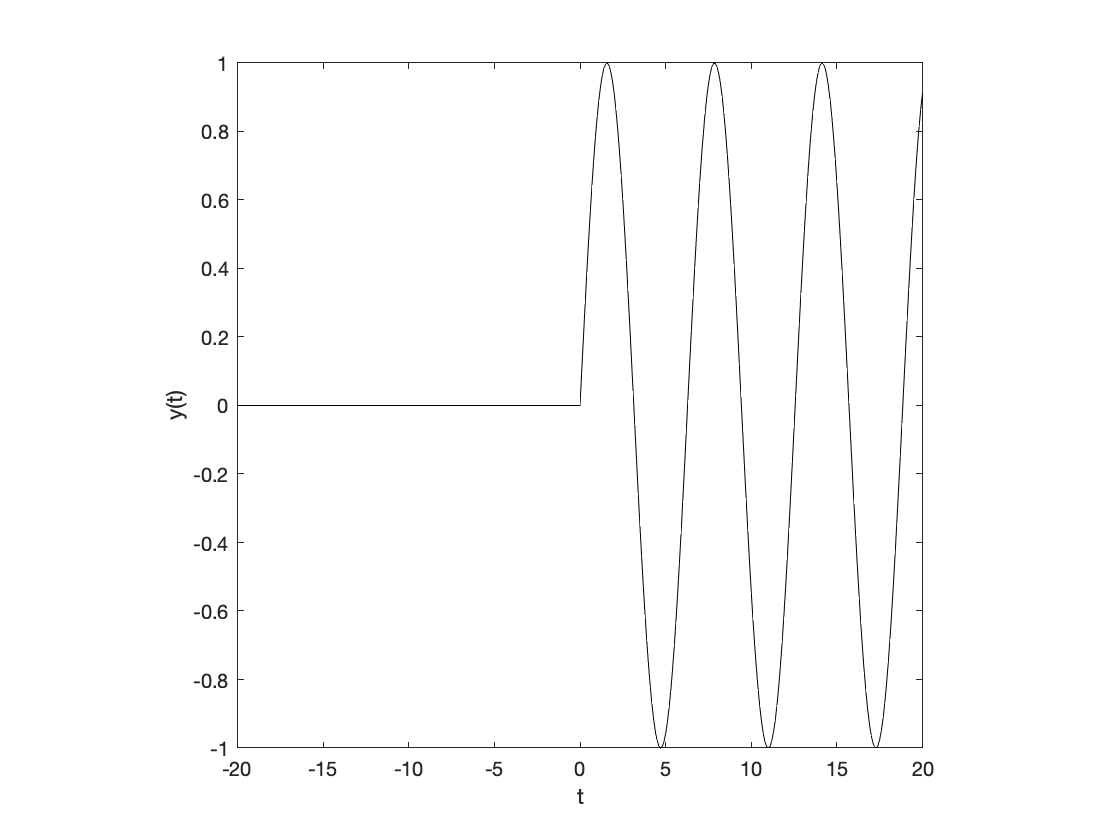

% time vector
t = -20:.1:20;
% Produce a plot of the causal signal y(t)
plot(t,sin(t).*(t>=0),'k-')
% Define plotting parameters
xlabel('t')
ylabel('y(t)')
axis square % The plot window becomes square
ylim([-1,1]) % Set the y limits

**Example**. Say we want to produce a half wave rectification of sine function. 

            
$$y\left(t\right)=\left\lbrace \begin{array}{ll}
\sin \left(t\right) & \sin \left(t\right)>0\\
0 & \sin \left(t\right)\le 0
\end{array}\right.$$


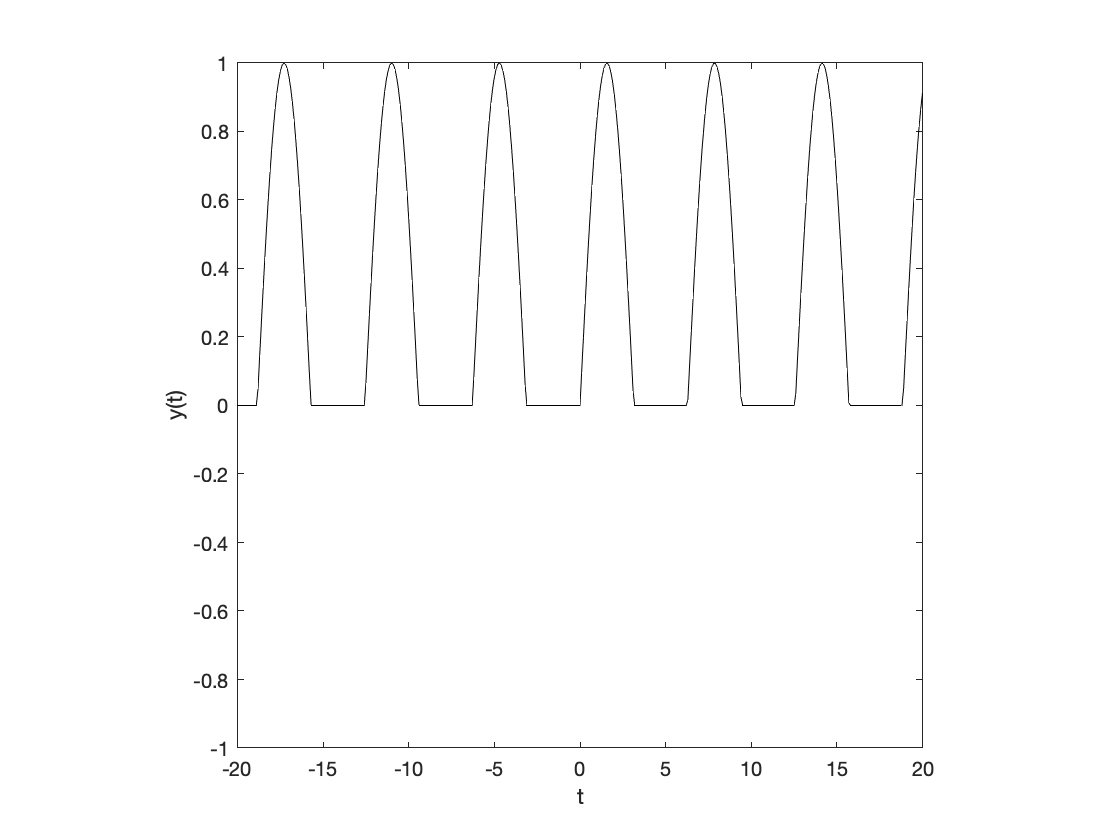

% time vector
t = -20:.1:20;
% Produce a plot of the causal signal y(t)
plot(t,sin(t).*(sin(t)>0),'k-')
% Define plotting parameters
xlabel('t')
ylabel('y(t)')
axis square % The plot window becomes square
ylim([-1,1]) % Set the y limits

**Note**: in both of the cases, multiplying the function by a logical array of the same size was a quick and efficient way to specify regions to be zero.

#### Built-in logical functions

- `any()` takes in an array or logical array and returns a scalar and logical `true` if any array values are `true.`

x = (1:4)>3

x = 1×4 logical array
   0   0   0   1


% TRUE if any element is true
any(x)

ans = logical
   1


- `all()` takes in an array or logical array and returns a scalar and logical `true` only if all values are `true`

x = (1:4)>3

x = 1×4 logical array
   0   0   0   1


% TRUE if all elements are true
all(x)

ans = logical
   0


- `isscalar()` takes an input and returns `true` if that input is a scalar.

x = 1:4

x =      1     2     3     4


% TRUE if any element is true
isscalar(x)

ans = logical
   0


- `isempty()` takes an input and returns `true` if that input is an empty set (`[]`).

x = 1:4

x =      1     2     3     4


% TRUE if any element is true
isempty(x)

ans = logical
   0


- `isnan()` takes an input and returns `true` if that input is not a number (`NaN`).

x = nan(1,3)

x =    NaN   NaN   NaN


% Element-wise evaluation -> a corresponding index is 1 if that entry is
% NaN
isnan(x)

ans = 1×3 logical array
   1   1   1


**Note**: MATLAB has many other built-in logical functions. These can be found at:

[https://www.mathworks.com/help/matlab/ref/is.html](https://www.mathworks.com/help/matlab/ref/is.html)

### Changing the shape of arrays

We have seen a few built-in functions for reshaping arrays, such as using the transpose (`'`). As a reminder, the transpose function rotates a matrix over its main diagonal, as seen here. This works for vectors and matrices.

% Create matrix
z = magic(3)

z =      8     1     6
     3     5     7
     4     9     2


z'

ans =      8     3     4
     1     5     9
     6     7     2


**Note**: transpose is not defined for >2D arrays in MATLAB.

#### Rotating and flipping arrays

MATLAB permits array rotations using the `rot90` and reflections using `fliplr`, `flipud``,`and `flip`. 

% Display matrix
z

z =      8     1     6
     3     5     7
     4     9     2


% Rotate matrix 90 degrees counter clockwise
rot90(z)

ans =      6     7     2
     1     5     9
     8     3     4


% Flip matrix "up and down," that is the last row becomes the first
flipud(z)

ans =      4     9     2
     3     5     7
     8     1     6


% This is equivalent to reversing the row order, but requires less code
z(end:-1:1,:)

ans =      4     9     2
     3     5     7
     8     1     6


% Flip matrix "left and right," that is the last column becomes the first
fliplr(z)

ans =      6     1     8
     7     5     3
     2     9     4


% This is equivalent to reversing the column order, but requires less code
z(:,end:-1:1)

ans =      6     1     8
     7     5     3
     2     9     4


% Flip the matrix along the specified dimension. This could work for higher
% order arrays
% 1: flip rows
% 2: flip columns
flip(z,1)

ans =      4     9     2
     3     5     7
     8     1     6


#### Reshaping arrays

An array may be reshaped using the `reshape()`, which requires that the product of the reshaped dimensions equals the product of the original array dimensions.

z

z =      8     1     6
     3     5     7
     4     9     2


z2 = reshape(z,1,9)

z2 =      8     3     4     1     5     9     6     7     2


**Note**: the indices of the initial and reshaped matrix are determined from single index (“unwrapped”) subscripts